# Main Function Facial Style Transfer

Code by: Nora Agah

%Detect if there's a face in the content image and get the boundary of
%faces if there is one
content_image = imread("Face2.jpg");

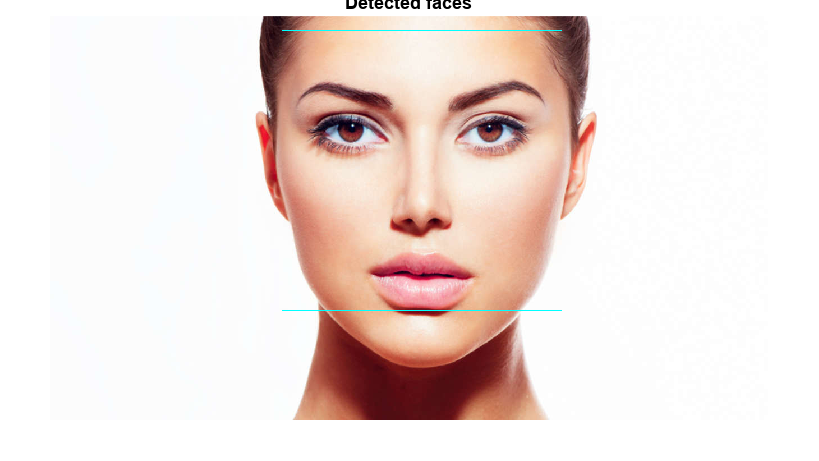

%cont_bbox is [x y width height]
[Content_Face_Presence, cont_bbox] = FaceDetection(content_image); 

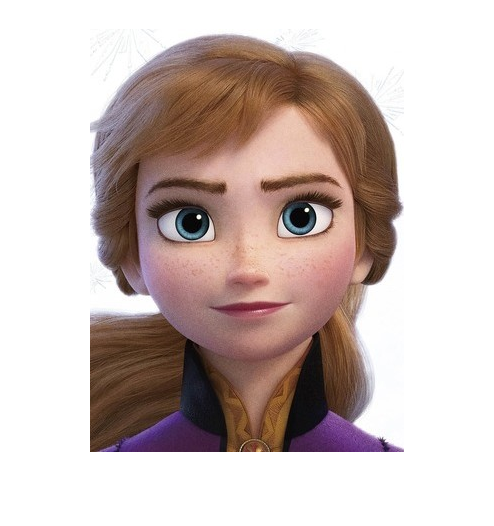

%Detect if there's a face in the style image and return boundaries of face
%if there is one
style_image = imread("AnnaFaceCropped.jpg");
figure();
imshow(style_image);

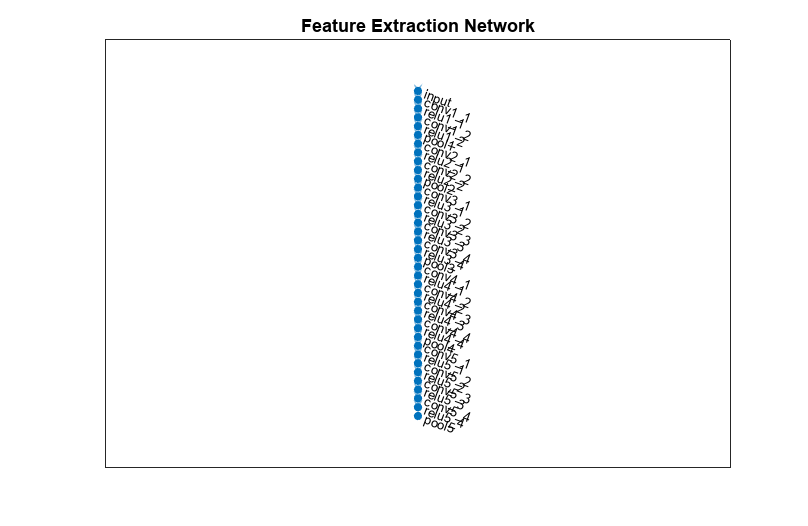

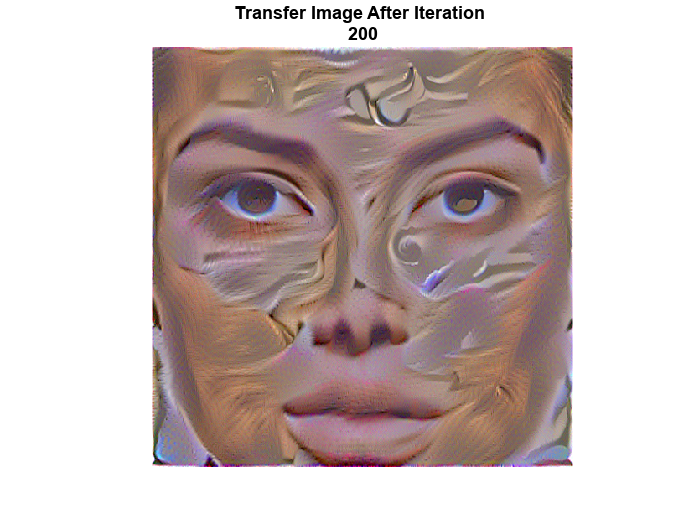

%Set to one if using code with face
Style_Face_Presence = 1; 
%If there is faces in both, use modified style transfer
if (Content_Face_Presence & Style_Face_Presence) == 1
    xstart = cont_bbox(1, 1);
    xend = cont_bbox(1, 1) + cont_bbox(1, 4);
    ystart = cont_bbox(1, 2);
    yend = cont_bbox(1, 2) + cont_bbox(1, 3);
    figure();
    imshow(content_image(ystart:yend, xstart:xend, :));
    transferimageface = StyleTransfer(content_image(ystart:yend, xstart:xend, :), style_image);
    figure();
    %transferimage =  StyleTransfer(content_image, style_image);
    %transferimage(ystart:yend, xstart:xend, :) = transferimageface;


else
    %If only faces in one, default to normal style transfer
    %transferimage = StyleTransfer(content_image, style_image);
end

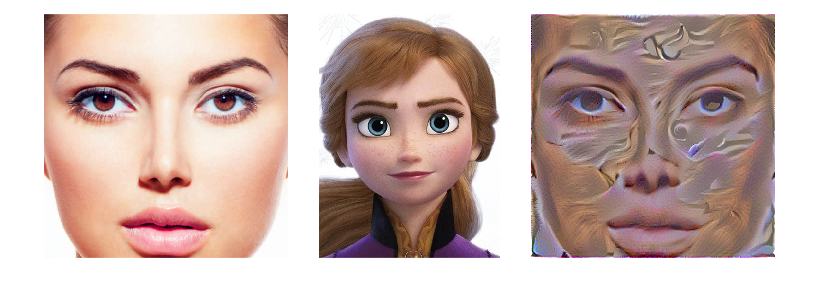

% Display the content image, transfer image, and style image al together
imshow(imtile({content_image(ystart:yend, xstart:xend, :),style_image,transferimageface}, ...
        GridSize=[1 3],BackgroundColor="w"));